%import UMAP embedding
data = readmatrix('UMAPembedding.csv');

%import list of images
rawImgs = readtable('20210517T1447z_LD32_dataFrame.csv');

matPlotLibColors = [195 76 80; 85 168 104; 76 114 176; 129 114 179; 26 26 26]./255;

planeIndex = int64(rawImgs(strcmp(rawImgs.Class, 'Plane'),:).Var1);
gliderIndex = int64(rawImgs(strcmp(rawImgs.Class, 'Glider'),:).Var1);
kiteIndex = int64(rawImgs(strcmp(rawImgs.Class, 'Kite'),:).Var1);
quadIndex = int64(rawImgs(strcmp(rawImgs.Class, 'Quadcopter'),:).Var1);
eagleIndex = int64(rawImgs(strcmp(rawImgs.Class, 'Eagle'),:).Var1);


planeData = 1*data(planeIndex+1, :);
gliderData = 1.*data(gliderIndex+1, :);
kiteData = 1.*data(kiteIndex+1, :);
quadData = 1.*data(quadIndex+1, :);
eagleData = 1.*data(eagleIndex+1, :);

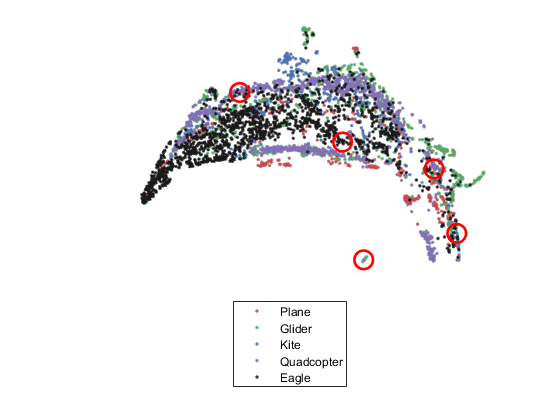

%Latent Space Vid points
figure;
set(gcf, 'color', 'white')
scatter(planeData(:, 1), planeData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(1, :))
hold on
scatter(gliderData(:, 1), gliderData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(2, :))
scatter(kiteData(:, 1), kiteData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(3, :))
scatter(quadData(:, 1), quadData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(4, :))
scatter(eagleData(:, 1), eagleData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(5, :))
legend({'Plane', 'Glider', 'Kite', 'Quadcopter', 'Eagle'}, 'Location', 'southoutside')

%biplane 66
plot(10.7974, 7.2329,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off') 

%quad 00
plot(6.7447, 4.2667,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')

%glider 98
plot(-0.4034, 9.7311,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')

%kite 95
plot(12.1075, 5.1299,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')

%eagle z04.13
plot(5.5274, 8.1120,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')

axis('off')

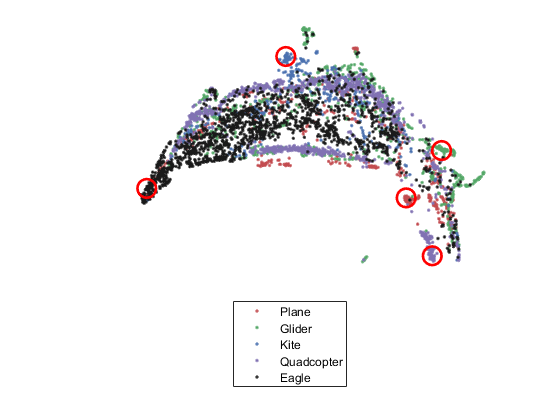

% Outlier points
figure;
set(gcf, 'color', 'white')
scatter(planeData(:, 1), planeData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(1, :))
hold on
scatter(gliderData(:, 1), gliderData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(2, :))
scatter(kiteData(:, 1), kiteData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(3, :))
scatter(quadData(:, 1), quadData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(4, :))
scatter(eagleData(:, 1), eagleData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(5, :))
legend({'Plane', 'Glider', 'Kite', 'Quadcopter', 'Eagle'}, 'Location', 'southoutside')

%plane vw_0076
plot(9.1906, 6.2895,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')
%glider VW_00560
plot(11.2297, 7.8357,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')
%kite Z02.38
plot(2.2578, 10.9064,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')
%quad z03.12
plot(10.694, 4.398,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')
%eagle z07.119
plot(-5.7527, 6.599,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')
axis('off')

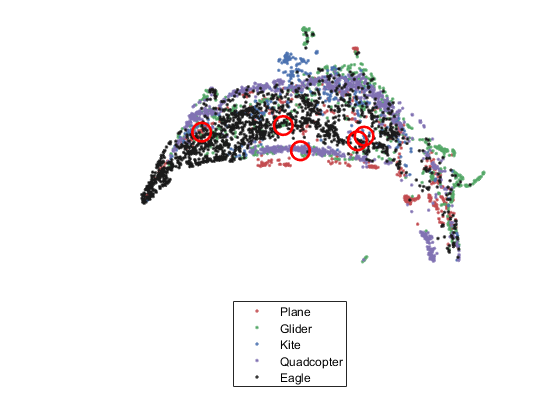

% central points
figure;
set(gcf, 'color', 'white')
scatter(planeData(:, 1), planeData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(1, :))
hold on
scatter(gliderData(:, 1), gliderData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(2, :))
scatter(kiteData(:, 1), kiteData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(3, :))
scatter(quadData(:, 1), quadData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(4, :))
scatter(eagleData(:, 1), eagleData(:, 2), 'Marker','.', 'MarkerEdgeColor',matPlotLibColors(5, :))
legend({'Plane', 'Glider', 'Kite', 'Quadcopter', 'Eagle'}, 'Location', 'southoutside')

% plane z06.0020
plot(-2.5907, 8.437,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')
% glider VW_00522
plot(2.1125, 8.6521,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')
%kite VW_00681
plot(6.7651, 8.3052,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')
%quad z03.0012
plot(3.1015, 7.8265,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')
%eagle z01.0064
plot(6.3845, 8.1523,...
    'o', 'MarkerSize',14, 'MarkerEdgeColor', 'r', 'LineWidth',2, 'HandleVisibility','off')
axis('off')